% Define the file path
%filePath = '/Users/jacoby/CHE260/lab 2 - part 2 a';
%filePath = '/Users/jacoby/CHE260/lab 2 - part2 b';
%filePath = '/Users/jacoby/CHE260/lab 2 - Part 2c';
%filePath = '/Users/jacoby/CHE260/lab 2 - part 2 d';

%filePath = '/Users/jacoby/CHE260/Lab 2 - Part 1a';
%filePath = '/Users/jacoby/CHE260/lab 2 - part 1 b';
%filePath = '/Users/jacoby/CHE260/lab 2 - part1 c';
%filePath = '/Users/jacoby/CHE260/lab 2 part 1 d';


fid = fopen(filePath, 'r');
for i = 1:3
    fgetl(fid);
end
data = readtable(filePath, 'FileType', 'text', 'Delimiter', '\t', 'HeaderLines', 3);
fclose(fid);
data = table2array(data)

data =          0   23.9000   23.6000   23.5000   23.4000   39.7000    0.1000         0         0
    0.1000   23.9000   23.4000   23.3000   23.3000   40.0000    0.4000         0         0
    0.2000   24.0000   23.6000   23.4000   23.2000   39.5000    0.3000         0         0
    0.3000   24.0000   23.6000   23.4000   23.2000   39.4000   -0.2000         0         0
    0.4000   23.9000   23.5000   23.3000   23.2000   39.4000   -0.2000         0         0
    0.5000   23.9000   23.5000   23.4000   23.3000   39.4000    0.3000         0         0
    0.6000   23.9000   23.5000   23.4000   23.3000   39.5000   -0.3000         0         0
    0.7000   24.0000   23.6000   23.4000   23.4000   39.7000    0.1000         0         0
    0.8000   23.8000   23.6000   23.4000   23.2000   40.0000    0.1000         0         0
    0.9000   23.8000   23.6000   23.4000   23.2000   39.5000    0.1000         0         0



time = data(:, 1);
T1 = data(:, 2);
Wall_temp = data(:, 3);
Top_plate = data(:, 4);
Bottom_plate = data(:, 5);
P1 = data(:, 6);
P2 = data(:, 7);
mass_flowrate = data(:, 8)

mass_flowrate =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


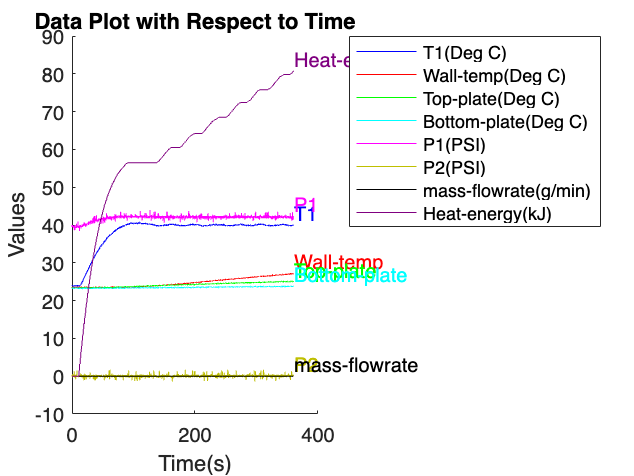

Heat_energy = data(:, 9);

figure; 
hold on; 

h1 = plot(time, T1, 'b');           
h2 = plot(time, Wall_temp, 'r');    
h3 = plot(time, Top_plate, 'g');    
h4 = plot(time, Bottom_plate, 'c'); 
h5 = plot(time, P1, 'm');           
h6 = plot(time, P2, 'Color', [0.75, 0.75, 0]);           
h7 = plot(time, mass_flowrate, 'k'); 
h8 = plot(time, Heat_energy, 'Color', [0.5, 0, 0.5]); 

% Add labels and title
xlabel('Time(s)');
ylabel('Values');
legend('T1(Deg C)', 'Wall-temp(Deg C)', 'Top-plate(Deg C)', 'Bottom-plate(Deg C)', 'P1(PSI)', 'P2(PSI)', 'mass-flowrate(g/min)', 'Heat-energy(kJ)', 'Location', 'bestoutside');
title('Data Plot with Respect to Time');

% Adding annotations close to the end of each line
text(time(end), T1(end), 'T1', 'Color', 'b', 'VerticalAlignment', 'bottom');
text(time(end), Wall_temp(end), 'Wall-temp', 'Color', 'r', 'VerticalAlignment', 'bottom');
text(time(end), Top_plate(end), 'Top-plate', 'Color', 'g', 'VerticalAlignment', 'bottom');
text(time(end), Bottom_plate(end), 'Bottom-plate', 'Color', 'c', 'VerticalAlignment', 'bottom');
text(time(end), P1(end), 'P1', 'Color', 'm', 'VerticalAlignment', 'bottom');
text(time(end), P2(end), 'P2', 'Color', [0.75, 0.75, 0], 'VerticalAlignment', 'bottom');
text(time(end), mass_flowrate(end), 'mass-flowrate', 'Color', 'k', 'VerticalAlignment', 'bottom');
text(time(end), Heat_energy(end), 'Heat-energy', 'Color', [0.5, 0, 0.5], 'VerticalAlignment', 'bottom');

hold off; % Release the hold


delta_t = 0.1 / 60;
mass_add = trapz(time/60, mass_flowrate)

mass_add = 0

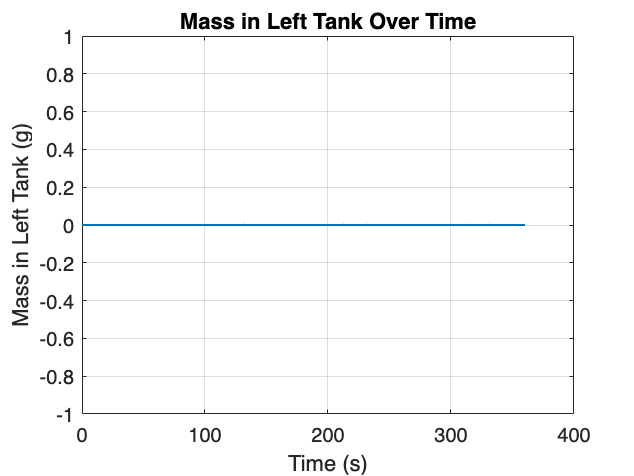


% Assuming 'time', 'T1', 'T2', 'P1', 'P2', and 'mass_flowrate' are vectors loaded from your data file
% Convert 'mass_flowrate' from g/min to g/s by dividing by 60
mass_flowrate = mass_flowrate / 60; % Convert to g/s

% Initialize cumulative mass added
m_added_to_tank = cumtrapz(time, mass_flowrate); % Integrate to get total mass added at each time step

% Constants for conversions
psig_to_Pa = 6894.76; % Conversion factor from psig to Pa
P_atm = 100100; % Atmospheric pressure in Pa

% Convert temperatures to Kelvin
T1 = T1 + 273.15; % Left Tank Temperature in Kelvin
T2 = 23.1 + 273.15; % Right Tank Temperature in Kelvin

% Convert gage pressures to absolute pressures in Pa
P1 = P1 * psig_to_Pa + P_atm; % Left Tank Absolute Pressure in Pa
P2 = P2 * psig_to_Pa + P_atm; % Right Tank Absolute Pressure in Pa

% Initialize an array to store the calculated mass in the left tank
m_left_tank = zeros(size(time));

% Calculate m_left_tank at each time step
for i = 1:length(time)
    % Using the formula to calculate m_left_tank at each time step
    m_left_tank(i) = m_added_to_tank(i) * (1 + 1 / (((P2(i) * T1(i)) / ((P1(i) * T2) - 1))));
end

% Plot the result
figure;
plot(time, m_left_tank, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Mass in Left Tank (g)');
title('Mass in Left Tank Over Time');
grid on;

m_left_tank

m_left_tank =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% Display final mass in the left tank
fprintf('The final mass inside the left tank is %.4f grams.\n', m_left_tank(end));

The final mass inside the left tank is 0.0000 grams.
